For the document network data, the input is two matrices including the m x n document content matrix W and the m x m citation link matrix C

clear classes

clear all
close all
clc

rng(213);        % code initialized
load('../Data/cora.mat');    % the sythetic temporary data file

%    W -- m x n     C -- m x m
lx = categorical(paper_classname);
[M, ~] = size(W);


Show the matrix structure

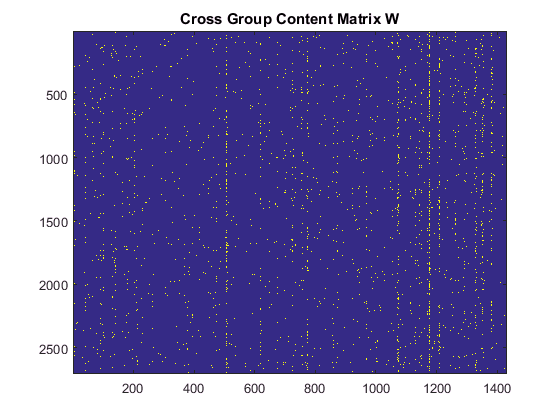

figure
imagesc(W);
title('Cross Group Content Matrix W');

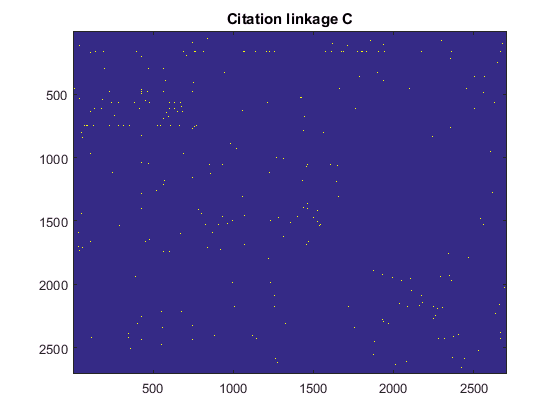


figure
C = C | C.';
imagesc(C);
title('Citation linkage C');

Using linear Transformation and Laplcian for dimensionality reduction

% %Normalized input data
% W = W - min(W(:));   % W = [k*C, W]; result in a lot of small eigenvalues
% W = W/max(W(:));
% W = bsxfun(@minus, W, mean(W,1));
% 
% d = sum(C,2);
% rd = 1./sqrt(d);
% Lc =  eye(M) - bsxfun(@times,bsxfun(@times,C,rd), rd');
% Lc = W'*Lc*W;
% 
% C_ = ~C;
% d_ = sum(C_,2);
% rd_ = 1./sqrt(d_);
% Lc_ =  eye(M) - bsxfun(@times,bsxfun(@times,C_,rd_), rd_');
% Lc_ = W'*Lc_*W;
% [P, Lambda] = eig(Lc, Lc_);
% [~, I] = sort(diag(Lambda), 'ascend');
% X = W*P;
% figure
% Plotcluster(X(:, [I(2),I(3)])', lx);
% title('Linear Laplacian embedding using C and W');

Revision No. 1

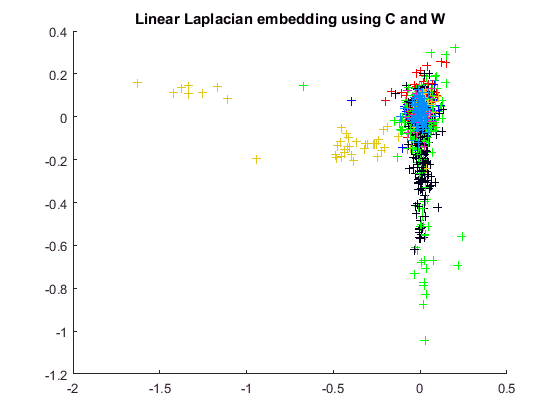

%Normalized input data
W = W - min(W(:));   % W = [k*C, W]; result in a lot of small eigenvalues
W = W/max(W(:));
W = bsxfun(@minus, W, mean(W,1));

d = sum(C,2);
Lc =  diag(d) - C;
Lc = W'*Lc*W;
Lc = (Lc + Lc.')/2;

C_ = full(~C);w
d_ = sum(C_,2);
Lc_ =  diag(d_) - C_;
Lc_ = W'*Lc_*W;
Lc_ = (Lc_ + Lc_')/2;
[P, Lambda] = eig(Lc, Lc_);
[~, I] = sort(diag(Lambda), 'ascend');
X = W*P;
figure
Plotcluster(X(:, [I(2),I(3)])', lx);
title('Linear Laplacian embedding using C and W');

% d = sum(T,2);        % T = [C, lambda*D];
% rd = 1./sqrt(d);
% Lc =  eye(size(T,1)) - bsxfun(@times,bsxfun(@times,T,rd), rd');
% [P, Lambda] = eig(Lc);
% [~, I] = sort(diag(Lambda), 'ascend');
% figure
% Plotcluster(P(:, [I(2),I(1)])', lx);
% title('Linear Laplacian embedding using C and W');

Visualize the data using tsne

cut_X = X(:, I(1:50));

% Compute pairwise distance matrix
sum_X = sum(cut_X .^ 2, 2);
D = bsxfun(@plus, sum_X, bsxfun(@plus, sum_X', -2 * (cut_X * cut_X')));

% Compute joint probabilities
P = d2p(D, 30, 1e-5);   

Computed P-values 500 of 2708 datapoints...
Computed P-values 1000 of 2708 datapoints...
Computed P-values 1500 of 2708 datapoints...
Computed P-values 2000 of 2708 datapoints...
Computed P-values 2500 of 2708 datapoints...
Mean value of sigma: 0.37659
Minimum value of sigma: 0.13548
Maximum value of sigma: 1.9448


Iteration 10: error is 52.1309
Iteration 20: error is 51.5546
Iteration 30: error is 50.2455
Iteration 40: error is 49.8489
Iteration 50: error is 49.606
Iteration 60: error is 49.5849
Iteration 70: error is 49.5743
Iteration 80: error is 49.6379
Iteration 90: error is 49.5247
Iteration 100: error is 3.6036
Iteration 110: error is 2.7626
Iteration 120: error is 2.2869
Iteration 130: error is 2.0466
Iteration 140: error is 1.9188
Iteration 150: error is 1.8277
Iteration 160: error is 1.7599
Iteration 170: error is 1.7063
Iteration 180: error is 1.6627
Iteration 190: error is 1.6262
Iteration 200: error is 1.5948
Iteration 210: error is 1.5674
Iteration 220: error is 1.5432
Iteration 230: error is 1.5218
Iteration 240: error is 1.5025
Iteration 250: error is 1.4851
Iteration 260: error is 1.4564
Iteration 270: error is 1.4227
Iteration 280: error is 1.3946
Iteration 290: error is 1.371
Iteration 300: error is 1.3507
Iteration 310: error is 1.3332
Iteration 320: error is 1.3179
Iteration 

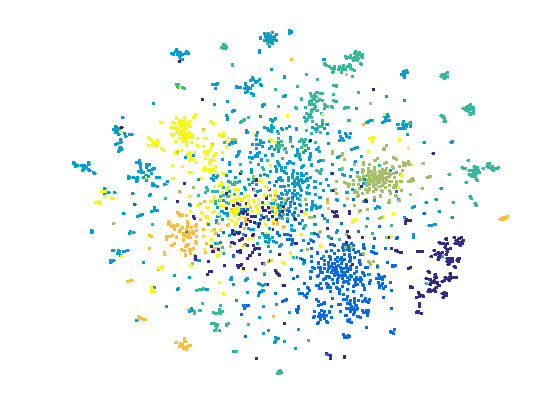

X_2d = tsne_p(P, lx, 2);

save the result

save('cora_algo3.mat');